mu = 0.012277471;
% re = @(x,y) ((x+mu).^2+y.^2).^.5;
% rm = @(x,y) ((x-1+mu).^2+y.^2).^.5;
% V = @(x,y) -log(mu./rm(x,y) + (1-mu)./re(x,y));
% fcontour(V,[-.4 1.2 -.5 .5],'fill','on','levelstep',.1,'meshdensity',80)
% axis equal,colorbar

mu = 0.012277471;
r3body(0,[1;2;3;4])

ans =    3.000000000000000
   4.000000000000000
   8.911210674775313
  -4.178456845957134


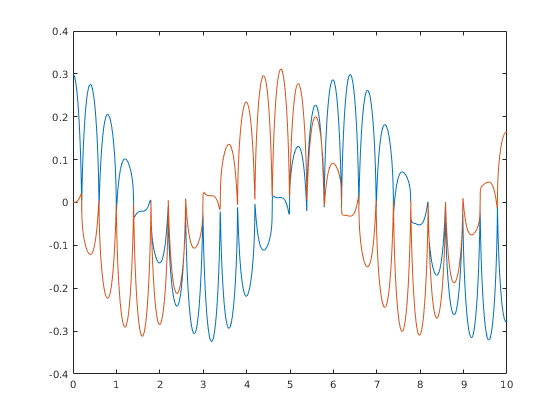

opt = odeset('reltol',1e-13,'abstol',1e-13);  
[t,u] = ode113(@r3body,linspace(0,10,2000),[0.3,0,0,0],opt);
clf, plot(t,u(:,1:2)) 

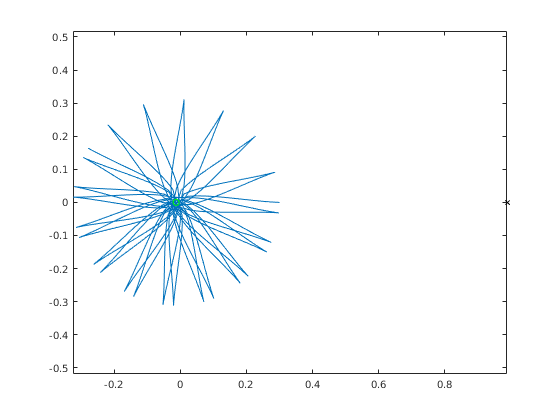

clf, plot(u(:,1),u(:,2))
hold on
plot(-mu,0,'go')
plot(1-mu,0,'kx')
axis equal

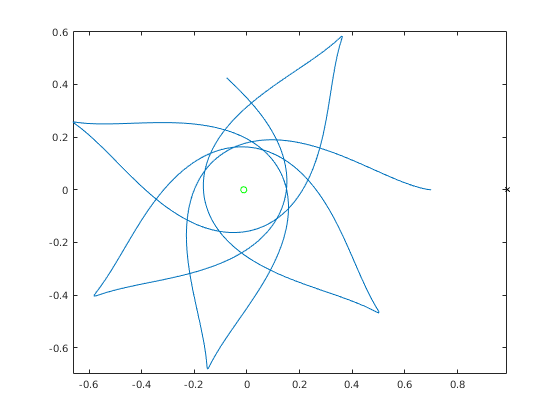

[t,u] = ode113(@r3body,linspace(0,10,2000),[0.7,0,0,0],opt);
clf, plot(u(:,1),u(:,2))
hold on
plot(-mu,0,'go')
plot(1-mu,0,'kx')
axis equal


% r3body(0,[0.5-mu,sqrt(3)/2,0,0])
% opt = odeset('reltol',1e-13,'abstol',1e-13);
% [t,u] = ode113(@r3body,linspace(0,200,2000),[0.5-mu,sqrt(3)/2,0,0],opt);
% plot(u(:,1),u(:,2))
% grid on

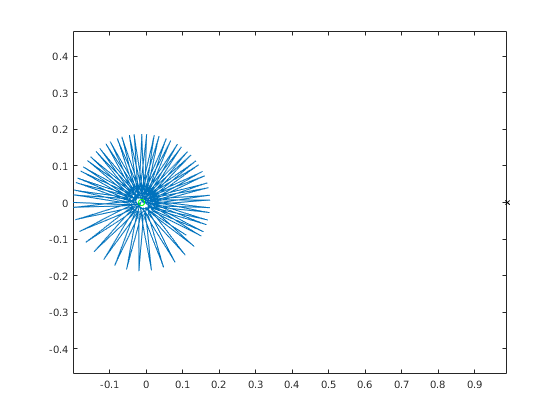

[t,u] = ode113(@r3body,linspace(0,10,2000),[-0.2,0,0,0],opt);
clf, plot(u(:,1),u(:,2))
hold on
plot(-mu,0,'go')
plot(1-mu,0,'kx')
axis equal

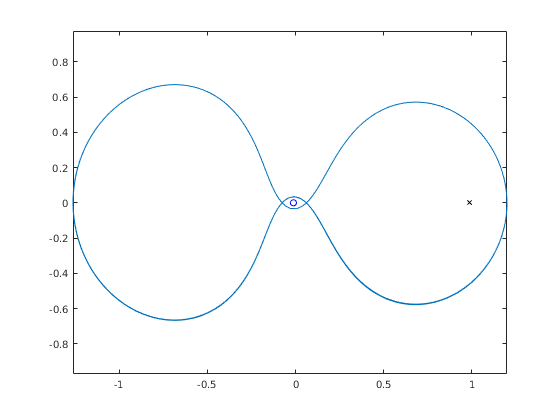

[t,u] = ode113(@r3body,linspace(0,10,2000),[1.2,0,0,-1.049357510],opt);
clf, plot(u(:,1),u(:,2))
hold on
plot(-mu,0,'go')
plot(1-mu,0,'kx')
axis equal

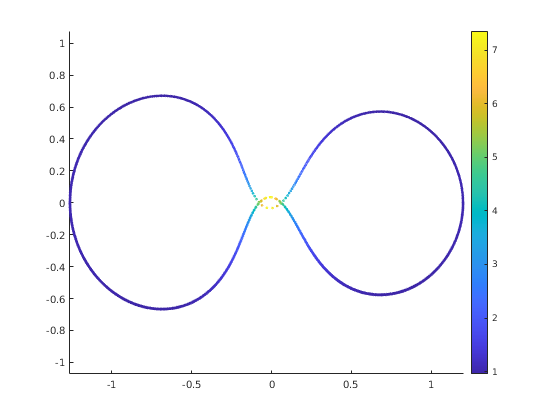

speed = sqrt(u(:,3).^2+u(:,4).^2);
clf, scatter(u(:,1),u(:,2),4,speed)
colorbar, axis equal

hold on
plot(-mu,0,'go')
plot(1-mu,0,'kx')

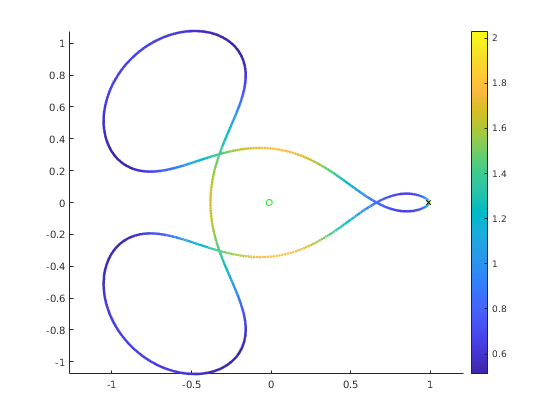

[t,u] = ode113(@r3body,linspace(0,20,2000),[.994,0,0,-2.03173262955734],opt);
speed = sqrt(u(:,3).^2+u(:,4).^2);
clf, scatter(u(:,1),u(:,2),4,speed)
colorbar, axis equal
hold on
plot(-mu,0,'go')
plot(1-mu,0,'kx')

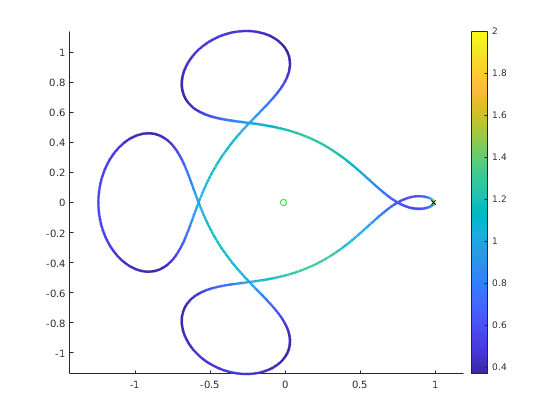

[t,u] = ode113(@r3body,linspace(0,20,2000),[.994,0,0,-2.00158510637908],opt);
speed = sqrt(u(:,3).^2+u(:,4).^2);
clf, scatter(u(:,1),u(:,2),4,speed)
colorbar, axis equal
hold on
plot(-mu,0,'go')
plot(1-mu,0,'kx')

[t,u] = ode113(@r3body,linspace(0,100,5000),[.994,0,0,-2.00158510637908],opt);

Unrecognized function or variable 'opt'.

speed = sqrt(u(:,3).^2+u(:,4).^2);
clf, scatter(u(:,1),u(:,2),4,speed)
colorbar, axis equal
hold on
plot(-mu,0,'go')
plot(1-mu,0,'kx')

r3body(0,[.994,0,0,-2.03173262955734])

re3 =    1.006277471000000


rm3 =    0.006277471000000


ans =                    0
  -2.031732629557340
  -4.069465259114680
                   0


function f = r3body(t,u)
x = u(1);  y = u(2);
xdot = u(3);  ydot = u(4);

mu = 0.012277471;
re3 = ((x+mu)^2+y^2)^1.5;
rm3 = ((x-1+mu)^2+y^2)^1.5;

xdotdot = 2*ydot + x - (1-mu)*(x + mu)/re3 - mu*(x - 1 + mu)/rm3;
ydotdot = -2*xdot + y - (1-mu)*y/re3 - mu*y/rm3;

f = [xdot;ydot;xdotdot;ydotdot];

end